%% multiparameter k medoid
% First we need waveform data! 
% Select 10 different waveform from sen

clear all; 
LoadCommonSettings_ericka;

rng(19970324)

SAT = 'S3A' ; 
defval('DOM',[60 90; -180 180])               %String that identifies region of interest/geographic quadrangle specified by [minLAT maxLAT; minLON maxLON]
defval('Retracker','SAMOSA2')                 %Retracker to be used
defval('SetRetr',{})
defval('DEM',[])    
defval('IDXpoi',[])          

FName = 'S3A_SR_1_SRA____20170401T004834_20170401T013904_20170426T154541_3029_016_088______MAR_O_NT_002.SEN3';

%% Read S3 L1b data and compute normalized waveforms 

[~,CS] = S3_L1b_read_ericka(FName)   ;
DDAcf   = DDA_ConfigFile(SAT,'SAR');
Wf_Norm_Aw = 1;      
%NORMfactor = 1./max(movmean(CS.SAR.data,Wf_Norm_Aw,1),[],1);
%wf   = NORMfactor .* CS.SAR.        c   v     v cv c c c c data;
wf = CS.SAR.data;

%newwf = [wf(:,1) wf(:,2) wf(:,3) wf(:,4) wf(:,5) wf(:,6) wf(:,4998) wf(:,4999) wf(:,5000) wf(:,5001)] ; 
newwf = wf(:,5000:10000) ; 
nwf = length(newwf(1,:)) ; 

[Dall, outlier_all] = D_matrix(newwf); 

Array indices must be positive integers or logical values.

Error in D_matrix (line 17)
            if  MAX_bin(i-1) < 0.125*MAX_value(i)

## KNN + Kmedoid

k_knn = 5 ; 

% Select fraction from the Kmedoid clusters to create a KNN training set 
n_train =  1000; 
n_test = nwf - n_train  ; 
train_idx = sort(randperm(nwf,n_train)) ; 
%train_idx = [1:3000]; 
test_idx = setdiff(1:nwf,train_idx) ; 

wf_train = newwf(:,train_idx) ; 
wf_test =  newwf(:,test_idx) ; 


[D_km, outlier_train, idxtrain_nooutliers, wftrain_nooutliers] = D_matrix(wf_train); 

DMAX done
Dww done
Dles done
Dtes done



outlier_train_all = train_idx(outlier_train) ; 
n_train_nooutliers = n_train - length(outlier_train) 

n_train_nooutliers = 2855


[~, outlier_test,~,~] = D_matrix(wf_test); 

DMAX done
Dww done
Dles done
Dtes done



%outlier_test_all = setdiff(outlier_all, outlier_train_all) ; 



k = 100;  % if k is too large for selected nwf, the index overlaps and in the end we will end up with less clusters 

label_train = ceil(k*rand(1,n_train_nooutliers));

last = zeros(1,n_train_nooutliers);
while any(label_train ~= last)                            % continue until convergence 
    [~,~,last(:)] = unique(label_train);                  % remove empty clusters
    [~, index] = min(D_km*sparse(1:n_train_nooutliers,last,1),[],1);    % find k medoids
    [val, label_train] = min(D_km(index,:),[],1);              % assign labels
end
energy = sum(val);
k_final = length(index) 

k_final = 14

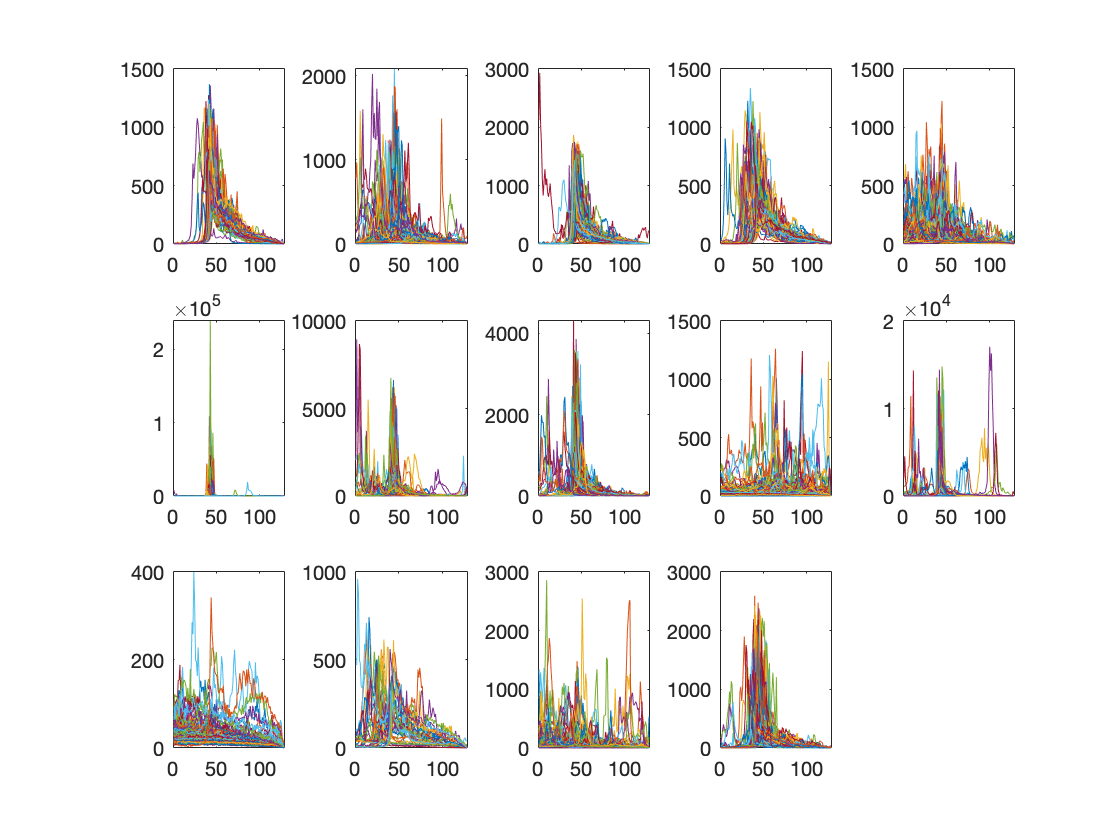


figure 
for i = 1:k_final
    subplot(3,5,i)
    for j = 1:length(find(label_train==i))
        ind = find(label_train==i); 
        plot(wftrain_nooutliers(:,ind(j)))
        hold on
    end     
end

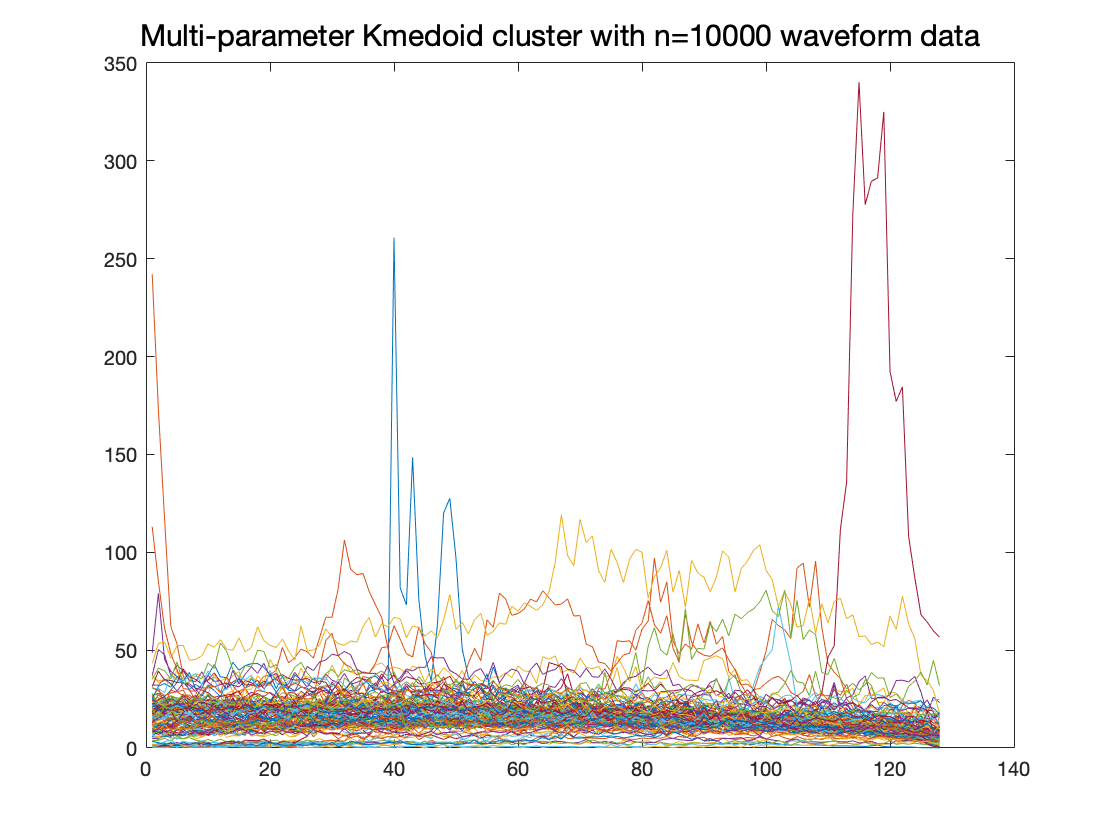


figure
plot(wf_train(:,outlier_train))

sgtitle("Multi-parameter Kmedoid cluster with n=" + nwf + " waveform data")

%% Asks input from the user 
prompt_lead = 'Which graph number can be classified as leads? If there are multiple, enter as an array (eg; [3,4,5])';
lead_k = input(prompt_lead) ; 
prompt_ice = 'Which graph number can be classified as ice? If there are multiple, enter as an array (eg; [3,4,5])';
ice_k = input(prompt_ice) ; 
prompt_ocean = 'Which graph number can be classified as ocean? If there are multiple, enter as an array (eg; [3,4,5])';
ocean_k = input(prompt_ocean) ; 
ambiguous_k = setdiff(1:k_final, lead_k) ; 
ambiguous_k = setdiff(ambiguous_k, ice_k) ; 
ambiguous_k = setdiff(ambiguous_k, ocean_k) ; 

labels = label_train ; % label of training data
%labels_test = label(test_idx) ; % label of test data
labels_test =zeros(1,n_test);

% initialize matrices
ed=zeros(n_test, n_train_nooutliers); %ed: (MxN) euclidean distances 
ed_ind=zeros(n_test, n_train_nooutliers);
k_nn=zeros(n_test,k_knn); %k-nearest neighbors for testing sample (Mxk)
predicted_labels=zeros(n_test,1);

%----------------------------------------------------------------
%-------MAKE THIS PART MORE EFFICIENT !!!!!!! -------------------
%----------------------------------------------------------------

% Make the distance matrix by reorganizing the original distance matrix D
for i = 1 :n_test 
    current_test_idx = test_idx(i)   ; 
    for j = 1 : n_train_nooutliers
    current_train_idx = idxtrain_nooutliers(j)   ;
    ed(i,j) = Dall(current_test_idx, current_train_idx) ; 
    end
    [ed(i,:),ed_ind(i,:)]=sort(ed(i,:)) ;
end

Index in position 1 exceeds array bounds (must not exceed 9484).


%find the nearest k for each data point of the testing data
k_nn=ed_ind(:,1:k_knn);
nn_index=k_nn(:,1);
%get the majority vote 
for i=1:size(k_nn,1)
    options=unique(labels(k_nn(i,:)'));
    max_count=0;
    max_label=0;
    for j=1:length(options)
        L=length(find(labels(k_nn(i,:)')==options(j)));
        if L>max_count
            max_label=options(j);
            max_count=L;
        end
    end
    predicted_labels(i)=max_label;
end

label_final = nan(1,nwf) ; 
label_final(train_idx) = labels; 
label_final(test_idx) = predicted_labels; %sorted back to the original order of SAR waveform 


%% READ S3 L1b data
LoadCommonSettings_ericka;

SAT = 'S3A' ; 
defval('DOM',[60 90; -180 180])               %String that identifies region of interest/geographic quadrangle specified by [minLAT maxLAT; minLON maxLON]
defval('Retracker','SAMOSA2')                 %Retracker to be used
defval('SetRetr',{})
defval('DEM',[])    
defval('IDXpoi',[])          

FName = 'S3A_SR_1_SRA____20170401T004834_20170401T013904_20170426T154541_3029_016_088______MAR_O_NT_002.SEN3';
[~,CS] = S3_L1b_read_ericka(FName)   ;



%% Code to raed OLCI GEO TIFF IMAGE 

% Locate OLCI Geo Tiff image : 
OLCIpath = "/Users/ericka/Desktop/Thesis/OLCIData" ; 
SEN3file = fullfile(OLCIpath, "S3A_OL_1_EFR____20170401T005019_20170401T005319_20180413T161703_0179_016_088_1620_LR2_R_NT_002.SEN3") ;
%SEN3file = fullfile(OLCIpath, "S3A_OL_1_EFR____20200317T103030_20200317T103313_20200318T150854_0163_056_108_1620_LN1_O_NT_002.SEN3") ;
OLCIfile = fullfile(OLCIpath, "S3A_OL_1_EFR____20170401T005019_20170401T005319_20180413T161703_0179_016_088_1620_LR2_R_NT_002_RGB.tif") ;
%OLCIfile = fullfile(OLCIpath, "S3A_OL_1_EFR____20170401T005019_20170401T005319_20180413T161703_0179_016_088_1620_LR2_R_NT_002_Oa08_radiance.tif");
%OLCIfile = fullfile(OLCIpath, "S3A_OL_1_EFR____20170401T005019_20170401T005319_20180413T161703_0179_016_088_1620_LR2_R_NT_002_Oa09_radiance.tif");

GEOfile = fullfile(SEN3file, "geo_coordinates.nc") ; 
OLCI = GEOTIFF_READ(OLCIfile);
OLCILATmin = min(OLCI.y);
OLCILATmax = max(OLCI.y);
OLCILONmin = min(OLCI.x) ; 
OLCILONmax = max(OLCI.x) ; 

% Find index of SAR data which corresponds to the image coordinates 
LONindex = find(CS.GEO.LON > OLCILONmin & CS.GEO.LON < OLCILONmax );
LATindex =  find(CS.GEO.LAT > OLCILATmin & CS.GEO.LAT < OLCILATmax ); 
validationindex = intersect(LONindex, LATindex) ; 


%% Classify waveforms 

DDAcf   = DDA_ConfigFile(SAT,'SAR');
Wf_Norm_Aw = 1;      
NORMfactor = 1./max(movmean(CS.SAR.data,Wf_Norm_Aw,1),[],1);
NORMdata   = NORMfactor .* CS.SAR.data;
unNORMdata =  CS.SAR.data;
 
Oa03 = ncread(fullfile(SEN3file, "Oa03_radiance.nc"), "Oa03_radiance");
Oa05 = ncread(fullfile(SEN3file, "Oa05_radiance.nc"), "Oa05_radiance");
Oa08 = ncread(fullfile(SEN3file, "Oa08_radiance.nc"), "Oa08_radiance");
lat = ncread(GEOfile, "latitude");
lon = ncread(GEOfile, "longitude");

for i = 1:length(lon(:,1))
    for j = 1:length(lon(1,:))
        if lon(i,j) < 0 
            lon(i,j) = lon(i,j) + 360;
        end 
    end
end

%%
% create true or false 3-color image
clear A ; 
A(:,:,1) = Oa08;  % red
A(:,:,2) = Oa05;  % green
A(:,:,3) = Oa03;  % blue


% Leads = 11 datosuruto..... 
%% 
leadindex =  intersect(find(label_final == lead_k ), validationindex); 
iceindex = intersect(find(label_final == ice_k ), validationindex); 




figure, worldmap([min(lat(:)) max(lat(:))],[min(lon(:)) max(lon(:))])
geoimg=geoshow(lat, lon, A/200,'DisplayType','image');  % this 200 was a bit random, depends on the maximum values in the bands
geoimg.AlphaDataMapping = 'none';
geoimg.FaceAlpha = 'texturemap';
alpha(geoimg,double(~isnan(Oa03)))
hold on 
scatterm(CS.GEO.LAT(iceindex),CS.GEO.LON(iceindex), 'filled', 'b'); 
scatterm(CS.GEO.LAT(leadindex),CS.GEO.LON(leadindex),  'filled', 'r'); 

 






